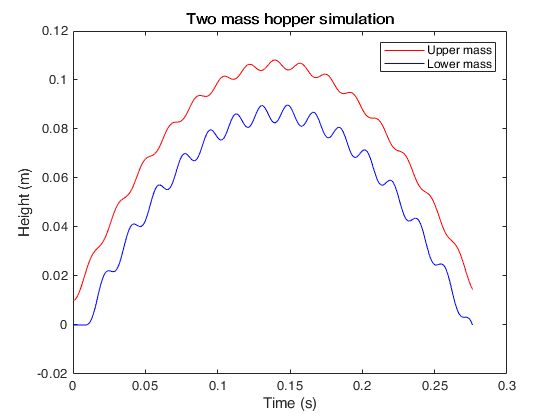

% Problem 2
clc
clearvars

% some system params
upper_m = 0.001;
lower_m = 0.0005;

l = 0.02;
k = 40;
g = 9.8;

[t,p] = hopper(upper_m,lower_m,l,k,g);

% part f
figure
plot(t,p(:,1),"r"), hold on
plot(t,p(:,3),"b")
title("Two mass hopper simulation")
xlabel("Time (s)")
ylabel("Height (m)")
legend(["Upper mass","Lower mass"])

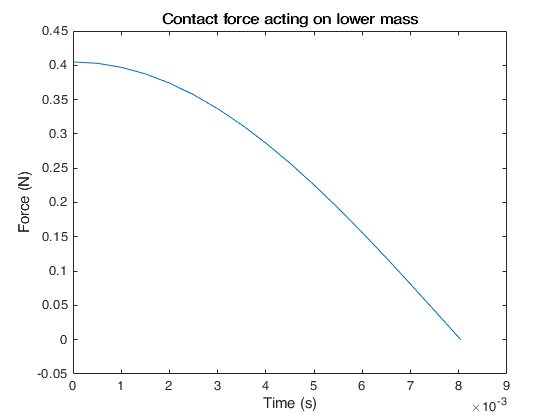


% part h
F_normal = lower_m*g + k*(l - p(:,1));
F_normal = F_normal(1:find(F_normal <= 0 ,1));

figure
plot(t(1:length(F_normal)),F_normal)
title("Contact force acting on lower mass")
xlabel("Time (s)")
ylabel("Force (N)")

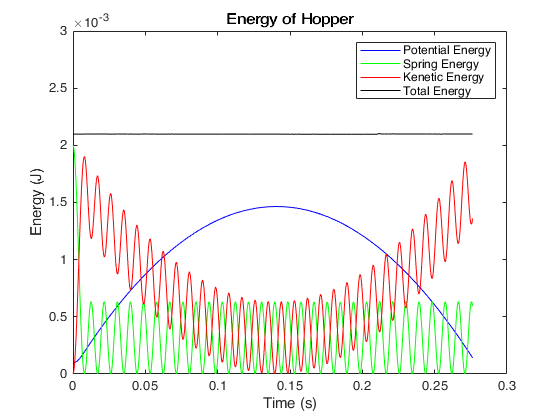


% part g
potential_E = upper_m*g*p(:,1) + lower_m*g*p(:,3);
spring_E = 0.5*k*(l-p(:,1)+p(:,3)).^2;
kenetic_E = 0.5*upper_m*p(:,2).^2 + 0.5*lower_m*p(:,4).^2;
total_E = potential_E + spring_E + kenetic_E;

figure
plot(t,potential_E,'b'), hold on
plot(t,spring_E,'g')
plot(t,kenetic_E,'r')
plot(t,total_E,'k')
ylim([0 .003])
legend(["Potential Energy","Spring Energy","Kenetic Energy","Total Energy"])
title("Energy of Hopper")
xlabel("Time (s)")
ylabel("Energy (J)")

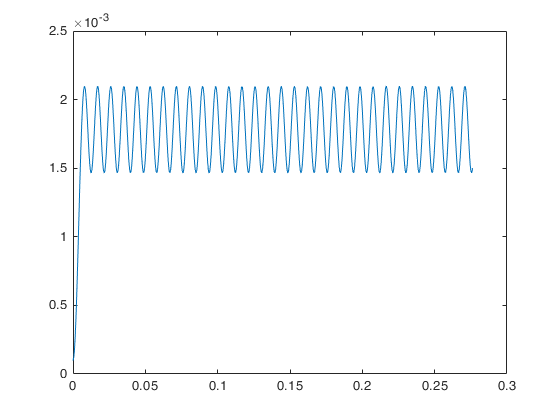


figure
plot(t,kenetic_E + potential_E)

function [t,p] = hopper(upper_m,lower_m,l,k,g)
    
    % system parameters
    mu = upper_m;     % kg
    ml = lower_m;    % kg
    
    tspan = [0:.0005:1];  % s
    
    % initial condistions
    % initial upper and lower position
    u_0 = 0.01; % m
    l_0 = 0;    % m
    
    % initial upper and lower velocity
    uv_0 = 0;   % m/s
    lv_0 = 0;   % m/s

    % pack initial conditions into column vector
    init_conditions = [u_0 uv_0 l_0 lv_0]';
    
    options_phase1 = odeset('Events', @eventFcnPhase1);
    options_phase2 = odeset('Events', @eventFcnPhase2);
    
    [t1,p1] = ode45(@phase1,tspan,init_conditions,options_phase1);
    
    [t2,p2] = ode45(@phase2,[t1(end):.0005:t1(end)+5],p1(end,:)',options_phase2);
    
    t = [t1; t2];
    p = [p1; p2];

    function dpdt = phase1(~,p)
        % 1st order equations
        uv = p(2);
        ua = k/mu*(l-p(1))-g;
        lv = 0;
        la = 0;
        
        dpdt = [uv ua lv la]';
    end
    
    function dpdt = phase2(~,p)
        % 1st order equations
        uv = p(2);
        ua = k/mu*(l-p(1)+p(3))-g;
        lv = p(4);
        la = -k/ml*(l-p(1)+p(3))-g;
        
        dpdt = [uv ua lv la]';
    end    

    function [position,isterminal,direction] = eventFcnPhase1(~,p)
        position = ml*g + k*(l-p(1)); % The value that we want to be zero
        isterminal = 1;  % Halt integration 
        direction = 0;   % The zero can be approached from either direction
    end
    
    function [position,isterminal,direction] = eventFcnPhase2(~,p)
        position = p(3); % The value that we want to be zero
        isterminal = 1;  % Halt integration 
        direction = 0;   % The zero can be approached from either direction
    end

end